# Visualize data after polynomial fitting

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\processed data");
addpath(fpath,dpath);
load 'processed data'\polynomial_fitted\tableStruct4_6th.mat

**Important conclusion**: Even for the most ideal case (Plateau), the position of T_max oscillates around a fixed location. 

Animation for data_10MPa_1.00h_Oil_20_deg_Stepped: 


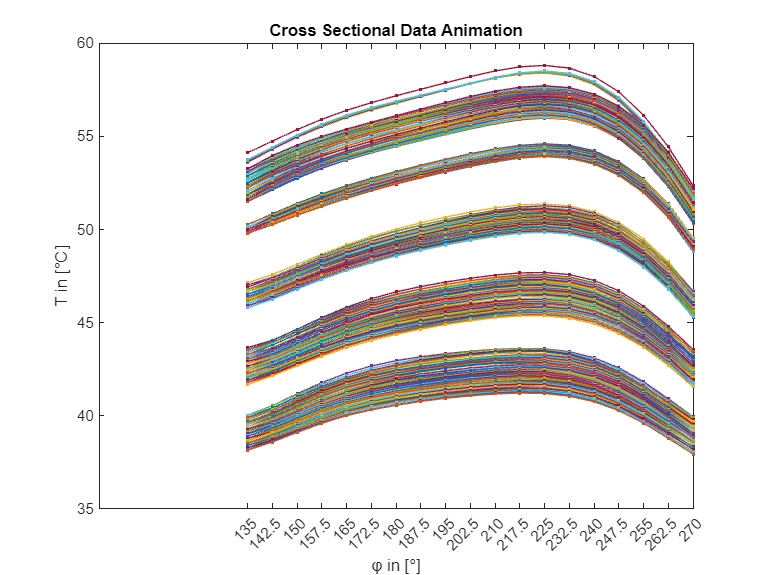

T_max position of data_10MPa_1.00h_Oil_20_deg_Stepped: 


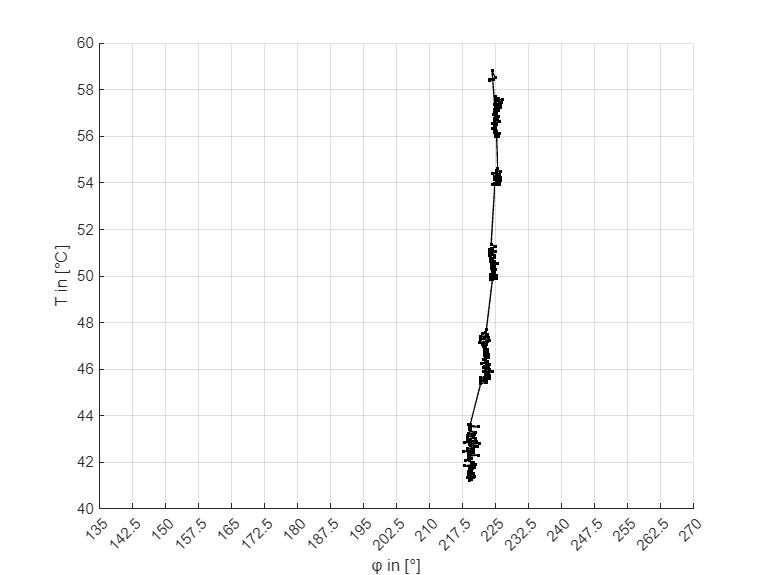

Animation for data_10MPa_1.00h_Oil_60_deg_Stepped: 


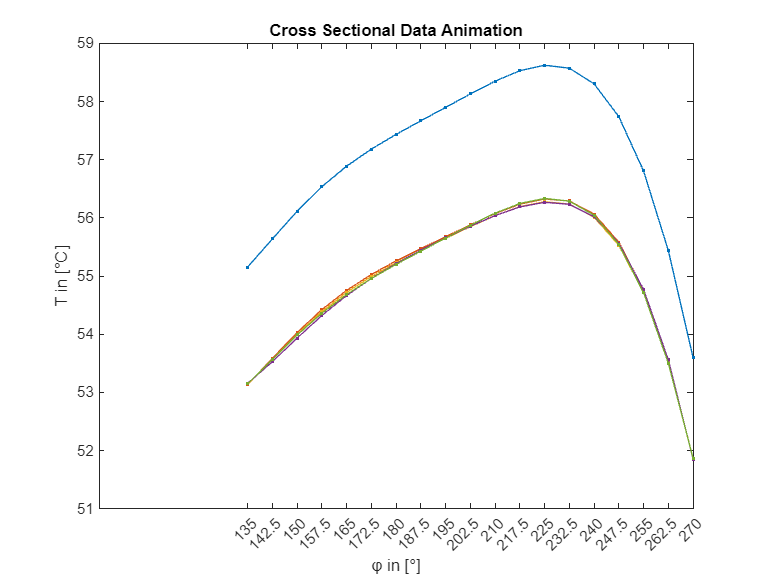

T_max position of data_10MPa_1.00h_Oil_60_deg_Stepped: 


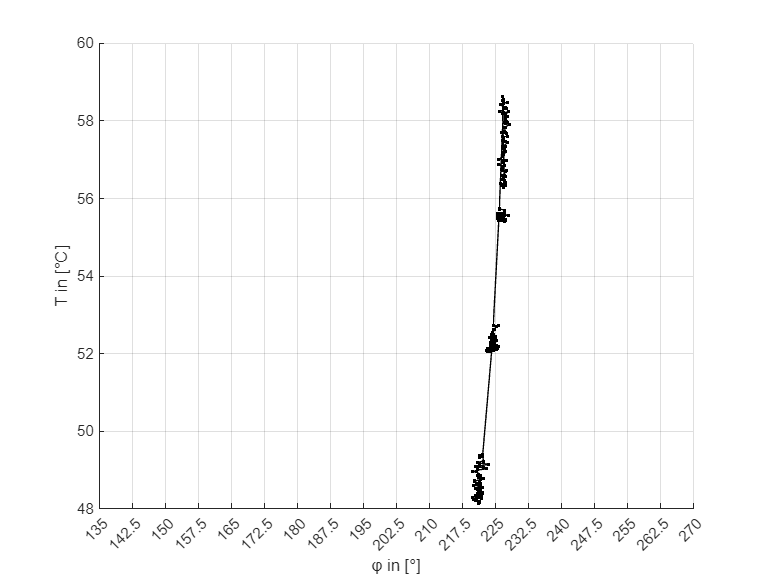

Animation for data_15MPa_1.00h_Oil_60_deg_Stepped: 


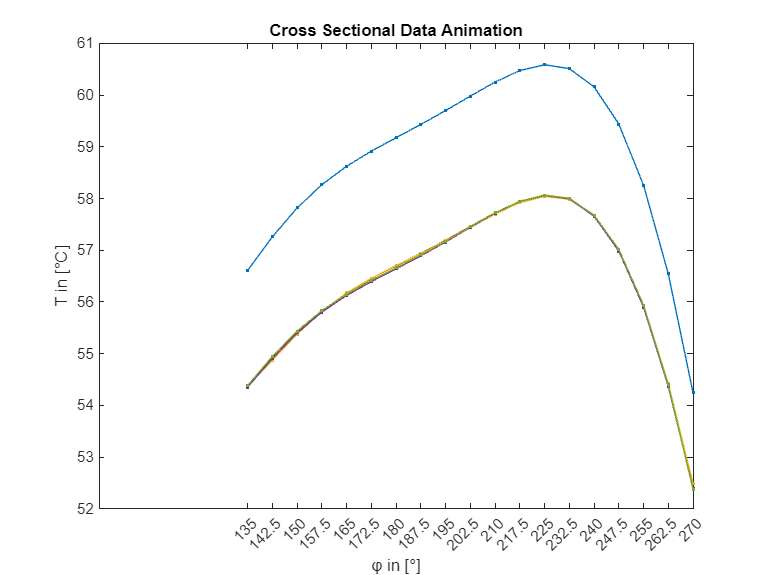

T_max position of data_15MPa_1.00h_Oil_60_deg_Stepped: 


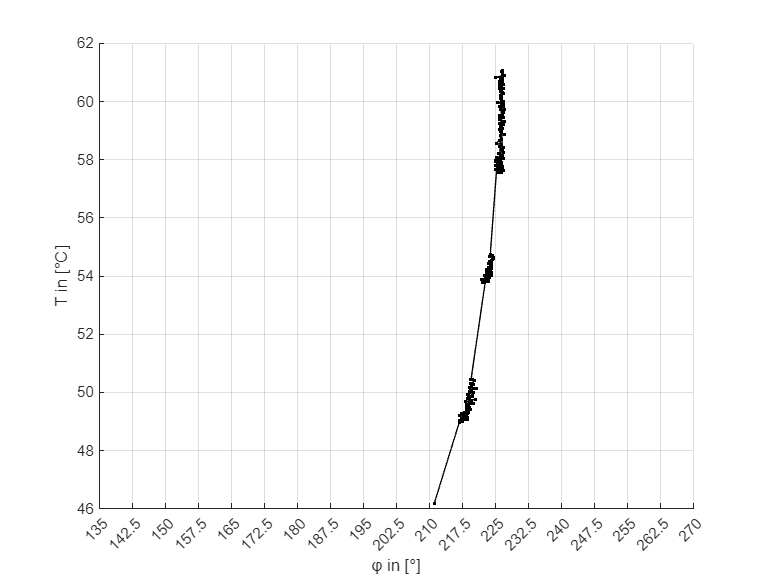

Animation for data_15MPa_6xh_Oil_60_deg_Plateau_discontinued: 


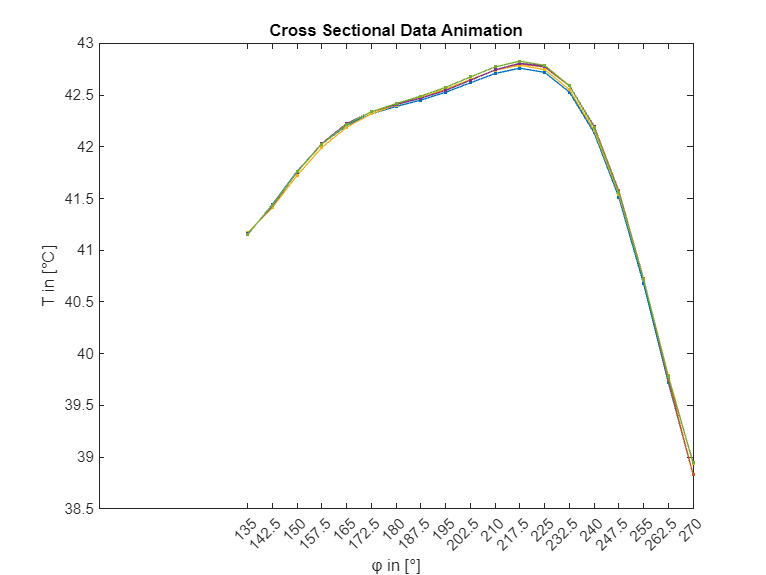

T_max position of data_15MPa_6xh_Oil_60_deg_Plateau_discontinued: 


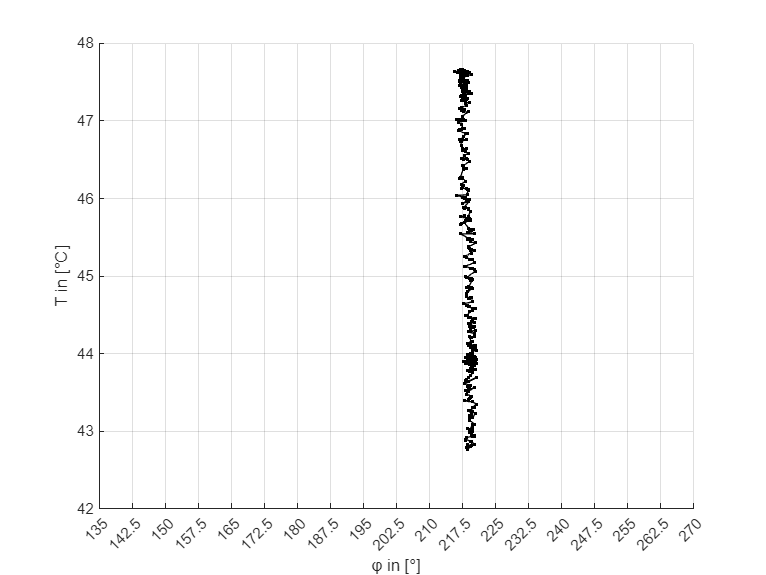

sensor_position = 135:7.5:270; % 排除了前五个传感器

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    %% Test Plan 可视化
    %testplan_visualization(t); 

    %% 时间截面动画
    timeCrossSection_animation(sensor_position,t,1);

    %% 最大值位置动画（参照相关函数重新手写）
    % 原因：原函数使用的是被替代后的表格数据！所以最大值位置动画与精确情形有偏差！

    table_maxT = tableStruct4(i).fitted_maxT;
        
    %创立figure
    fig = figure; 
    ax = axes; 
    an = animatedline(Marker=".",MarkerSize=6);

    %给fig命名
    set(fig, "Name", "T_max position of "+ t.Properties.Description);
    disp(get(fig, 'Name')+": "); %显示figure名称

    %xlabel,xlim,xticks,ylabel
    xlabel(ax,'φ in [°]'), xlim(ax,[135 270]); % 更改了x轴范围
    xticks(ax,sensor_position);
    ylabel(ax,"T in [°C]");
    grid on

    %动画开始
    for j = 1:height(table_maxT)
        
        % 添加数据点
        addpoints(an,table_maxT{j,1},table_maxT{j,2});
        drawnow;
    end
    % 强制显示图像
    savefig; openfig;

end

clear t table_maxT

### Test for the Plateau case if φ_Tmax ~ N(μ,σ)

One-sample Kolmogorov-Smirnov test

Null hypothesis: the data in vector `x` comes from a standard normal distribution

- If `h` `= 1`, this indicates the rejection of the null hypothesis at the 5% significance level.

- If `h` `= 0`, this indicates a failure to reject the null hypothesis at the `Alpha` significance level.

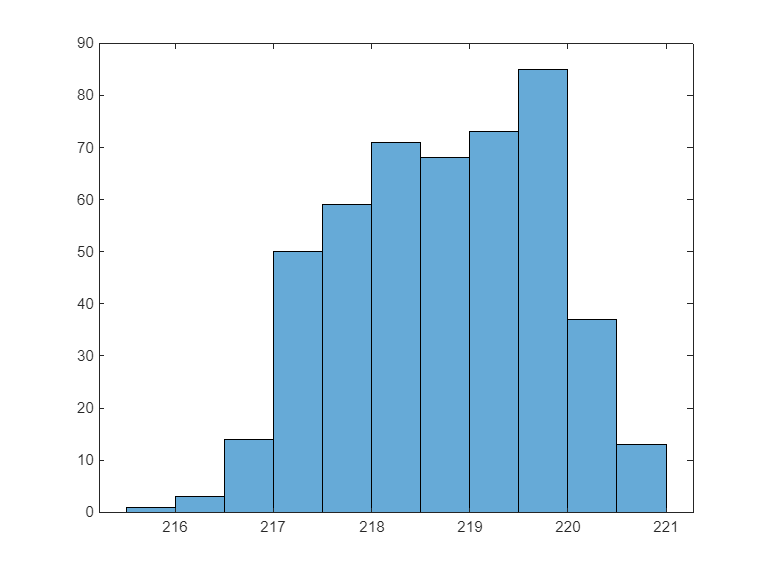

load 'processed data'\polynomial_fitted\tableStruct4_6th.mat

phi_Tmax_vals = tableStruct4(4).fitted_maxT{:,"T_position"};
histogram(phi_Tmax_vals)


mean_value = mean(phi_Tmax_vals) % sample mean

mean_value = 218.7629

std_value = std(phi_Tmax_vals) % sample standard deviation

std_value = 1.0368

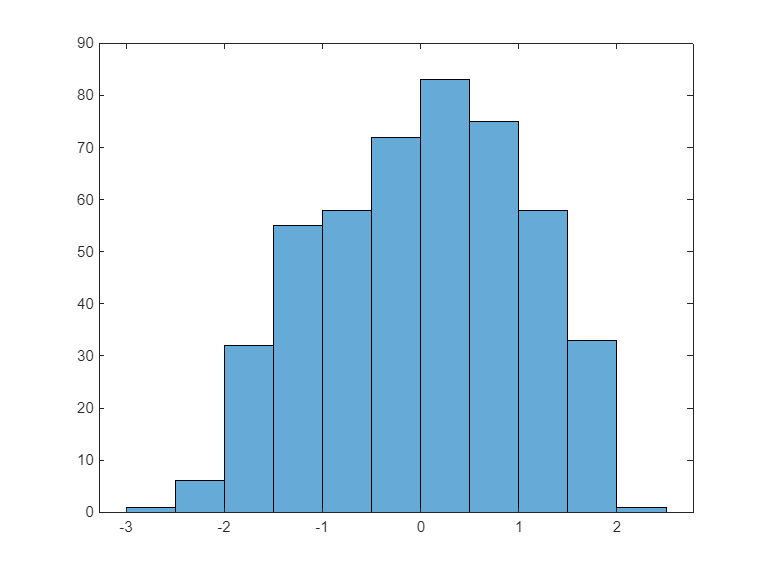


% standardize
x = (phi_Tmax_vals-mean_value)/std_value;
histogram(x)


% Kolmogorov-Smirnov test
[h,p] = kstest(x);
if h == 0
    fprintf('数据符合正态分布（p值 = %.4f）\n', p);
else
    fprintf('数据不符合正态分布（p值 = %.4f）\n', p);
end

数据符合正态分布（p值 = 0.0628）



% Lilliefors test
[h, p] = lillietest(x);

if h == 0
    fprintf('数据符合正态分布（p值 = %.4f）\n', p);
else
    fprintf('数据不符合正态分布（p值 = %.4f）\n', p);
end

数据不符合正态分布（p值 = 0.0010）



% Anderson-Darling 检验
[h, p] = adtest(x);

if h == 0
    fprintf('数据符合正态分布（p值 = %.4f）\n', p);
else
    fprintf('数据不符合正态分布（p值 = %.4f）\n', p);
end

数据不符合正态分布（p值 = 0.0005）
